# MCAMBERRRRRRR

%=============================================
% MK10 Tire Review Script
% Authors: Rohan Shinde || Jenna Lacuata
% Functions
    % Determine Testing Cases (3)
    % Calculate Tire Forces and Moments using MFeval and .tir files
    % Plot Lateral and Longitudinal Graphs with Additional Formatting
    % Calculate peaks, slopes, behaviour of plots

% For Questions -> Rohan Shinde
%=============================================

## Array & Parameter Extraction

% INSTRUCTIONS:
% -> Try not to change P1 (we chose 12PSI as a test pressure)
% -> Add additional params by extracting correct column from output (check Notion for column info)
% -> Make all calculations here (be sure to change index for each tire)

%loads tir file
tirFile = "./tirFiles/magicformula_R20.tir";
%create a cell for each camber

camberAngles = {1,2,3,4,5,6,7,8,9,10};

TireVCamberData = cell(1, length(camberAngles));


%populate cells with tire data
for i = 1:length(camberAngles)
    % parses tir file to get raw data matricies
    [FL_Output, FR_Output, RL_Output, RR_Output] = VD11_MFeval_TIR_File_Parser(tirFile, 200, 8, 111, camberAngles{i});
    % get and declare all constants
    [FL_ForceZ, FR_ForceZ, RR_ForceZ, RL_ForceZ, kappa, alpha, gamma, phit, Vx, P ] = VD_11_Constants();
    % put raw data matricies into a vector
    TireRawData = {FL_Output, FR_Output, RL_Output, RR_Output};
    
    %clears the "Tire" variable so we can repopulate it
    clear Tire

    % for each wheel on the car (FL, FR, RL, RR) process each wheel
    for j = 1:4
        %stores into a struct array
        Tire(j) = VD11_Process_Tire( TireRawData{j} );
    end

    %assigns the struct array that corresponds to the tire model to cell
    TireVCamberData{i} = Tire;
end

## Plotting and Graphical Analysis

% INSTRUCTIONS:
% -> Based on either lat or long analysis, comment and uncomment plotting blocks
% -> For lateral analysis plots - USE LATERAL labelled blocks
% -> For longitudinal plots - USE LONGITUDINAL labelled blocks

%which wheel we wanna compare (1 = FL, 2 = FR, 3 = RL, 4 = RR)
colors = {'r','g','b','y'}

colors = 1×4 cell array
    {'r'}    {'g'}    {'b'}    {'y'}


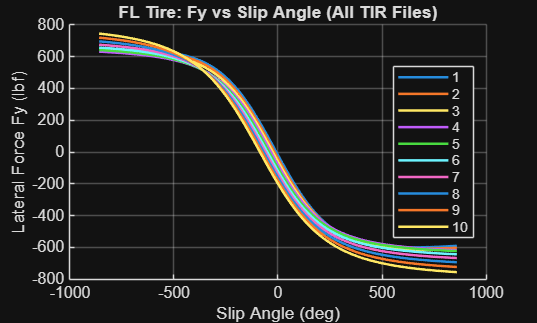

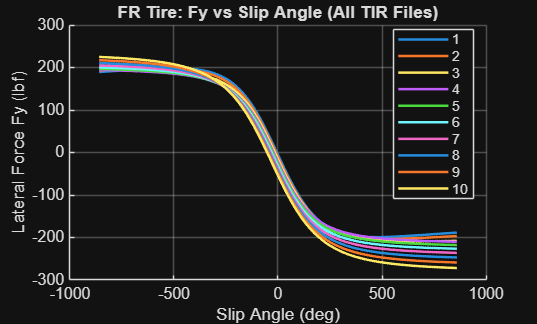

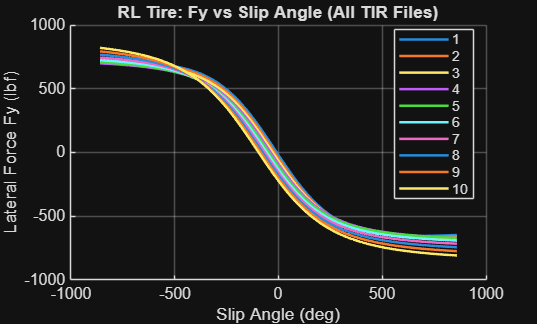

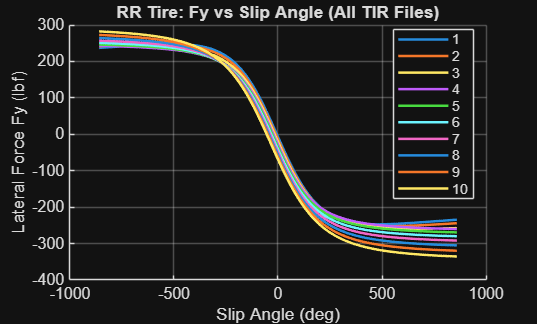

wheelIdx = 1;

for i = 1:4
    wheelIdx = i;
    % set up plot
    figure; hold on; grid on
    
    for f = 1:length(TireVCamberData)
        Tire = TireVCamberData{f}(wheelIdx);
        plot(Tire.SA, Tire.Fy, 'LineWidth', 1.5)
    end
    
    xlabel('Slip Angle (deg)')
    ylabel('Lateral Force Fy (lbf)')
    legend(string(camberAngles), 'Location', 'best')
    
    % all wheel specific plot settings go here
    switch(wheelIdx)
        case 1
            title('FL Tire: Fy vs Slip Angle (All TIR Files)');
        case 2
            title('FR Tire: Fy vs Slip Angle (All TIR Files)');
        case 3
            title('RL Tire: Fy vs Slip Angle (All TIR Files)');
        case 4
            title('RR Tire: Fy vs Slip Angle (All TIR Files)');
    end
end